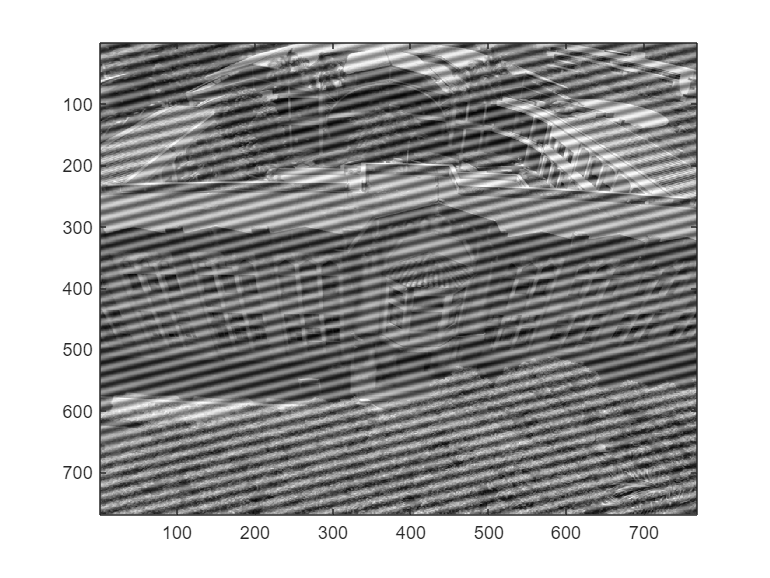

imagenConRuido = imread("b.png");
imagesc(imagenConRuido)
colormap("gray")

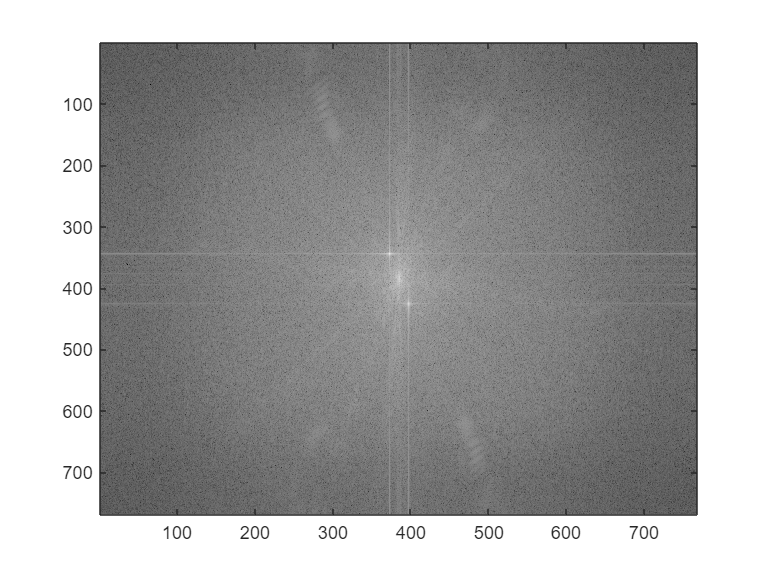

FFTimRuido = (fftshift(fft2(imagenConRuido)));
imagesc(log10(abs(FFTimRuido)))

%FFTimRuido(384-10:384+10,384-10:384+10) = 0;

%[maximosY,maximosX] = find(FFTimRuido == max(FFTimRuido,[],"all"))
maximosY =[344;426];
maximosX = [373;397];

rectSize = 10;
FFTimRuido(maximosY(1)-rectSize:maximosY(1)+rectSize,maximosX(1)-rectSize:maximosX(1)+rectSize) = 0;
FFTimRuido(maximosY(2)-rectSize:maximosY(2)+rectSize,maximosX(2)-rectSize:maximosX(2)+rectSize) = 0;

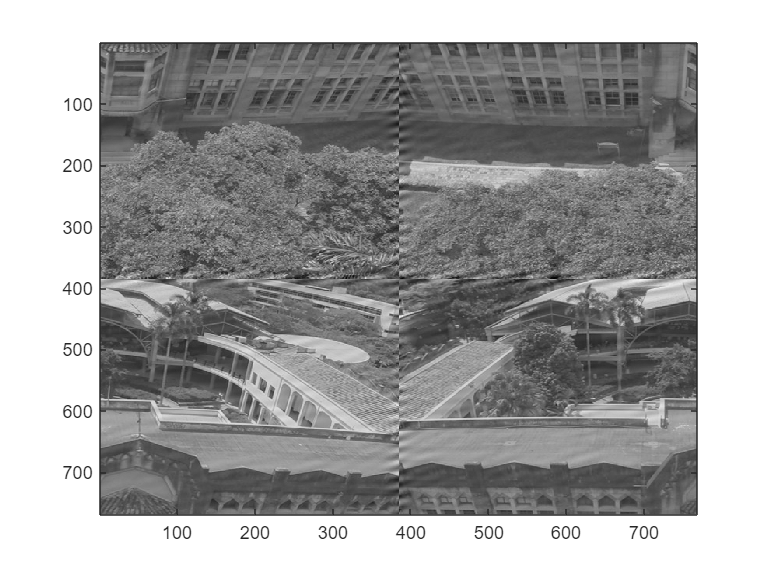

imagenFiltrada =abs(fftshift(ifft2(ifftshift(FFTimRuido))));
imagesc((imagenFiltrada))

[h,w] = size(imagenFiltrada)

h = 768

w = 768

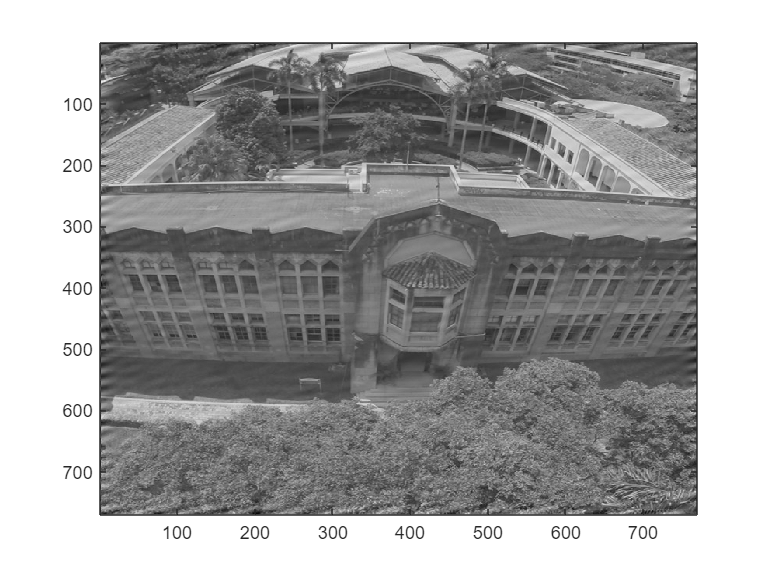

imagenParte1 = imagenFiltrada(h/2:h,w/2:w);
imagenParte2 = imagenFiltrada(h/2:h,1:w/2);
imagenParte3 = imagenFiltrada(1:h/2,w/2:w);
imagenParte4 = imagenFiltrada(1:h/2,1:w/2);

imagenFinal = cat(1,cat(2,imagenParte1,imagenParte2),cat(2,imagenParte3,imagenParte4));
imagesc(imagenFinal)